# いろいろ練習用

obj.A = randn(4,4);
obj.B = randn(4,2);
obj.C = randn(4,4);

Param = struct('A', obj.A, 'B', obj.B)

Param = フィールドをもつ struct :
    A: [4×4 double]
    B: [4×2 double]


A = 2 * rand(3,3) + 0.5

A =     1.2063    0.5860    1.9634
    2.1424    0.8380    1.7955
    0.5308    1.7982    1.4018



B = max(-2, min(2, A))

B =     1.2063    0.5860    1.9634
    2.0000    0.8380    1.7955
    0.5308    1.7982    1.4018


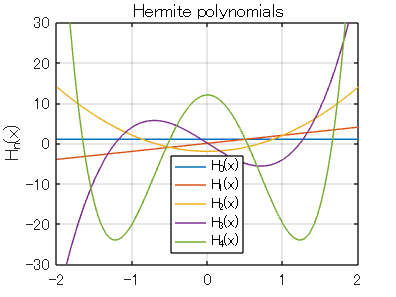

syms x y
fplot(hermiteH(0:4,x))
axis([-2 2 -30 30])
grid on

ylabel('H_n(x)')
legend('H_0(x)', 'H_1(x)', 'H_2(x)', 'H_3(x)', 'H_4(x)', 'Location', 'Best')
title('Hermite polynomials')

% t = 0:0.01:2*pi;
% x = sin(t);
x = Data.X

x =     0.0861    0.0862    0.0862    0.0862    0.0862    0.0861    0.0861    0.0860    0.0860    0.0859    0.0858    0.0857    0.0856    0.0855    0.0853    0.0853    0.0852    0.0850    0.0849    0.0848    0.0846    0.0844    0.0843    0.0841    0.0840    0.0838    0.0836    0.0834    0.0833    0.0830    0.0829    0.0829    0.0827    0.0825    0.0824    0.0822    0.0821    0.0819    0.0818    0.0817    0.0815    0.0814    0.0813    0.0811    0.0810    0.0809    0.0808    0.0807    0.0806    0.0805


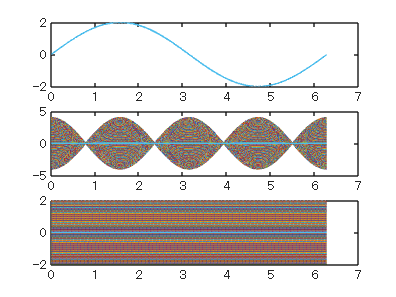

要求された 78175x1x1x78175 (45.5GB) 配列は、最大配列サイズの基本設定 (15.8GB) を超えています。これにより、MATLAB は反応しなくなる可能性があります。

エラー: kron (行 35)
   K = reshape(A.*B, ma*mb, na*nb);

関連ドキュメンテーション

y0 = hermiteH(0, x);
y1 = hermiteH(1, x);
y2 = hermiteH(2, x);

figure(1);
% subplot(3,1,1); plot(t, y0);
% subplot(3,1,2); plot(t, y1);
subplot(3,1,1); plot(t, kron(y0,y1'));

subplot(3,1,2); plot(t, kron(y1,y2'));
subplot(3,1,3); plot(t, kron(y1,y0'));

% figure(2);
% subplot(3,1,1); plot(t, y2);

string(datetime('now'), 'yyyy-MM-dd_hh-mm-ss')

ans = "2024-09-18_12-09-12"